% DEMOJRMPCSYNTHETIC   Example of using jrmpc into synthetic data.
%    This example loads numel(theta) views from ./syntheticData/ and calls
%    jrmpc to do the registration. It creates 4 plots one with the initial
%    position of the point sets, one which shows the registration at
%    every iteration, one with the final alignment achieved after maxNumIter
%    iterations and one with the "cleaned up" point sets. Directory 
%    ./syntheticData/ contains 4 partial views from the stanford bunny, 
%    each view is degraded with disparsity noise and outliers. The angles in
%    theta are ground truth angles (same for all 3 axes) used in the 
%    construction.
%
%    $ 18 / 12 / 2014 3:24 PM $

clc
close all
clear all
 
% number of iterations to be run
maxNumIter = 100;                    
                     



% number of views, M files must be found in the directory ./syntheticData 
M = 4;

% cell with indexes 1:M, used as suffixes on view's filenames
idx = transpose(0:3); 

% string-labels for legends in subsequent plots
strIdx = arrayfun(@(j) sprintf('view %d',j),idx,'uniformoutput',false);

load data


fprintf(' Data loading...\n');

 Data loading...


% load gt
rootfolder = '../'

rootfolder = '../'

currentfolder = 'tartanair_toy_exp_50_0.5/'

currentfolder = 'tartanair_toy_exp_50_0.5/'

index = 0

index =      0


index_s = int2str(index)

index_s = '0'

gtfilename = append(rootfolder,currentfolder,index_s,'/gt_poses.txt')

gtfilename = '../tartanair_toy_exp_50_0.5/0/gt_poses.txt'

A = readmatrix(gtfilename);
Tgtr = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';

% load point cloud 
percentage = 0.1

percentage =    0.100000000000000



V1 = pcread(append(rootfolder,currentfolder,index_s,'/0normal.pcd'))';
[n,m] = size(V1)

n =      1


m =      1



V2 = pcread(append(rootfolder,currentfolder,index_s,'/1normal.pcd'))';
V3 = pcread(append(rootfolder,currentfolder,index_s,'/2normal.pcd'))';
V4 = pcread(append(rootfolder,currentfolder,index_s,'/3normal.pcd'))';
V1.Location

ans = 474×3 single matrix
  -1.1889955   1.1991578   2.8675165
  -0.1709939   1.3075259   1.0719154
   0.8258926   1.0057421   0.7558464
  -0.1250468  -1.1454716   1.8635600
  -1.4360976   2.0766096   2.3482115
  -1.4764901   1.3803115   1.9244845
   0.2703482   0.9726827   1.3838288
  -3.0690923   2.2309940   3.0816522
  -2.6860111   2.4498782   4.0663552
  -4.7051735   1.7195786   2.2488730


V2.Location

ans = 586×3 single matrix
  -0.4282919  -0.5196949   2.5591824
  -1.1486309  -1.1049750   3.1346402
   2.1762381  -1.5064008   3.2015102
   0.4023107   0.7104019   2.9169302
   3.3206151  -0.5298344   0.9396425
  -0.8256128  -1.8362273   2.0207925
  -0.7563750  -0.7006513   2.8970129
  -0.0632806  -1.8766600   1.3325280
  -2.4062667  -1.6457479   4.0552106
   1.3965224  -1.0709479   3.4666007


% 
% V1_down = pcdownsample(V1,'random',percentage,PreserveStructure=true);
% V2_down = pcdownsample(V2,'random',percentage,PreserveStructure=true);
% V3_down = pcdownsample(V3,'random',percentage,PreserveStructure=true);
% V4_down = pcdownsample(V4,'random',percentage,PreserveStructure=true);V1_down.Location 
% writematrix(V1_down.Location,'down.csv') ;
% writematrix(V1.Location,'full.csv');
% [Lia, Locb]  = ismember(V1_down.Location,V1.Location,'rows')
% V1_p = bsxfun(@plus,Tgtr{1}(1:3,1:3) *V1.Location',Tgtr{1}(1:3,4));
% V2_p = bsxfun(@plus,Tgtr{2}(1:3,1:3) *V2.Location',Tgtr{2}(1:3,4));
% V3_p = bsxfun(@plus,Tgtr{3}(1:3,1:3) *V3.Location',Tgtr{3}(1:3,4));
% V4_p = bsxfun(@plus,Tgtr{4}(1:3,1:3) *V4.Location',Tgtr{4}(1:3,4));
V1_p = V1.Location';
V2_p = V2.Location';
V3_p = V3.Location';
V4_p = V4.Location';

for j =1:M
    Tgtr{j} = inv(Tgtr{j});
end

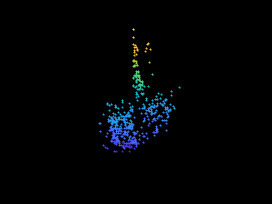


ptCloud_before = pcread(append(rootfolder,currentfolder,index_s,'/before_BA_bunny_',index_s,'.pcd'));
ptCloud_after = pcread(append(rootfolder,currentfolder,index_s,'/after_BA_bunny_',index_s,'.pcd'));
ptCloud_gt = pcread(append(rootfolder,currentfolder,index_s,'/gt_BA_bunny_',index_s,'.pcd'));

pcshow(V1);

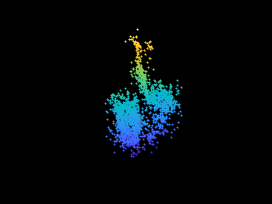




pcshow(ptCloud_gt);


V = {V1_p,V2_p,V3_p,V4_p}'

V = 4×1 cell array
    {3×474 single}
    {3×586 single}
    {3×533 single}
    {3×540 single}


size(V)

ans =      4     1


% Vf = {V1_p,V2_p,V3_p,V4_p}'
% V = {V1.Location',V2.Location'}'
% ground truth rotation matrices Rgt{j}*V{j} is aligned with Rgt{1}*R{1}


% colors for each view
clrmap = {[1 .1412 0]; [1 .1412 0]; [1 .1412 0]; [1 .1412 0]};
% markerSizes 
markerSize = {30; 30; 30; 30};
% markers
marker = {'s'; 's'; 's'; 's'};
% initialize GMM means Xin, using random sampling of a unit sphere. Choose
% your own initialization. You may want to initialize Xin with some of the
% sets.

Calculate initial estimate 

% set K as the 50% of the median cardinality of the views
test = {V1_p}

test = 1×1 cell array
    {3×474 single}


K = ceil(0.5*median(cellfun(@(V) size(V,2),test))); 

% sample the unit sphere, by randomly selecting azimuth / elevation angles
az = 2*pi*rand(1,K);
el = 2*pi*rand(1,K);

%points on a unit sphere
Xin = [cos(az).*cos(el); sin(el); sin(az).*cos(el)];% (unit) polar to cartesian conversion

Xin = Xin; % it is good for the initialization to have initial cluster centers at the same order with the points
% since sigma is automatically initialized based on X and V

Plot initial position


% % % show the initial position of the point clouds
% % figure(1);
% % hold on,grid on
% % 
% % % make the legend
% % title('Initial position of the point clouds','fontweight','bold','fontsize',12);
% % scatter3(V{1}(1,:),V{1}(2,:),V{1}(3,:),markerSize{1},clrmap{1},marker{1})
% % scatter3(V{2}(1,:),V{2}(2,:),V{2}(3,:),markerSize{2},clrmap{2},marker{2})
% % scatter3(V{3}(1,:),V{3}(2,:),V{3}(3,:),markerSize{3},clrmap{3},marker{3})
% % scatter3(V{4}(1,:),V{4}(2,:),V{4}(3,:),markerSize{4},clrmap{4},marker{4})
% % scatter3(Xin(1,:),Xin(2,:),Xin(3,:),'k')
% % %scatter3(V2.Location(:,1),V2.Location(:,2),V2.Location(:,3),7)
% % 
% % 
% % 
% % % set(1,'position',get(1,'position')+[-260 0 0 0]);
% % 
% % 
% % view([-69.66 28.04])
% % 
% %        
% % % scatter3(Xin(1,:),Xin(2,:),Xin(3,:),'k')
% % hold off; drawnow
% % 




run data registration

 XLim = get(gca,'XLim');
       
 YLim = get(gca,'YLim');
       
 Zlim = get(gca,'ZLim');
fprintf('Data registration... \n\n');

Data registration... 




% % call JRMPC (type jrmpc with no arguments to see the documentation).
tic
[R,t,X,S,a,~,T] = jrmpc(V,Xin,'maxNumIter',maxNumIter,'gamma',0.5);
toc

Elapsed time is 0.779331 seconds.


% measure and display convergency, view 1 is ommited as is the referential.

% Convert R,t to ground truth T
Tres = {[],[],[],[]};

for j =1:M
   Tres{j} = [[R{j},t{j}];[0,0,0,1]];
   Tres{j} = Tres{j};
end
for j=1:M
    Tfixed_res{j}= inv(Tres{1})*Tres{j};

end
Tfixed_res = Tfixed_res'

Tfixed_res = 4×1 cell array
    {4×4 single}
    {4×4 single}
    {4×4 single}
    {4×4 single}


size(Tres)

ans =      1     4


% measure and display convergency, view 1 is ommited as is the referential.
fprintf('                  ||inv(A{j})*Tgtr{j} - I||_F                  \n');

                  ||inv(A{j})*Tgtr{j} - I||_F                  



fprintf('______________________________________________________________\n');

______________________________________________________________



fprintf('Set  :'),for j=2:M,fprintf('    %d    ',j),end,fprintf('\n');

Set  :    2        3        4    


for j=2:M
    current_error = norm(inv(Tfixed_res{j})*Tgtr{j} - eye(4),'fro');
    fprintf('  %.4f ',current_error);
end

  14.0345   13.1475   12.3991 


fprintf('\n');

visualize the registration process, see documentation of jrmpc for T.


figure(2);
A = readmatrix(append(rootfolder,currentfolder,index_s,'/rkhs_results.txt'));
Tcvo = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
TV = cellfun(@(V,T) bsxfun(@plus,T(1:3,1:3)*V,T(1:3,4)),V,Tfixed_res,'uniformoutput',false);


plot 

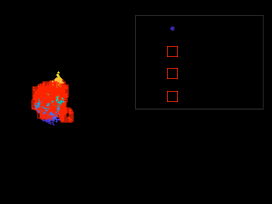

 
[TVrefined,Xrefined,Xrem] = removePointsAndCenters(TV,X,S,a);
% TVrefined = TV
% TVrefined{1} = TV{1};
% TVrefined{2} = TV{2};
% 
% TVrefined{3} = TV{3};
% TVrefined{4} = TV{4};
% visualize TVrefined.

figure(3);
hold on, grid on

    title('Final registration with unreliable points removed','fontweight','bold','fontsize',12);
    
    hg3 = cellfun(@(TVrefined,clrmap,marker,mkSize) scatter3(TVrefined(1,:),TVrefined(2,:),TVrefined(3,:),mkSize,clrmap,marker),TVrefined,clrmap,marker,markerSize);
    
    legend(strIdx{:});
    
    % use the same axes as in the registration process
%     set(gca,'XLim',XLim,'YLim',YLim,'ZLim',Zlim,'fontweight','bold','children',hg3);
    
    set(3,'position',get(1,'position')+[0 -510 0 0]);
    
    view([38.63 14.99])
hold off


% % Visualize bad centers (orange) and good centers (blue).
% figure(4);
% hold on, grid on
% 
%     title('Final GMM means.','fontweight','bold','fontsize',12);
%     
%     scatter3(Xrefined(1,:),Xrefined(2,:),Xrefined(3,:),8,[0 .38 .67],'s');
%     
%     scatter3(Xrem(1,:),Xrem(2,:),Xrem(3,:),40,[1 .1412 0],'marker','x');
%     
%     legend('"Good" Centers','"Bad" Centers');
%     
%     % use the same axes as in the registration process
%     set(gca,'XLim',XLim,'YLim',YLim,'ZLim',Zlim,'fontweight','bold');
%     
%     set(4,'position',get(1,'position')+[+580 -510 0 0]);
%     
%     view([40 54])
%     
% hold off

% log pose 
line = zeros(4,16);
for j = 1:M
    line(j,:) = reshape(Tres{j}',[1,16]);
end
line = round(line,6)

line =    0.264220000000000  -0.437230000000000   0.859662000000000  -6.937810000000000   0.933613000000000  -0.107684000000000  -0.341718000000000   2.884450000000000   0.241981000000000   0.892880000000000   0.379751000000000  -4.099641000000000                   0                   0                   0   1.000000000000000
   0.416446000000000   0.897669000000000  -0.144095000000000  -1.242685000000000   0.568322000000000  -0.133323000000000   0.811933000000000  -7.772609000000000   0.709636000000000  -0.420019000000000  -0.565686000000000  -0.608054000000000                   0                   0                   0   1.000000000000000
   0.718666000000000   0.624029000000000  -0.306769000000000  -2.013013000000000   0.626035000000000  -0.388636000000000   0.676049000000000  -7.507615000000000   0.302652000000000  -0.677902000000000  -0.669963000000000  -0.252880000000000                   0                   0                   0   1.000000000000000
   0.199944000000000   0.95423

Tres{1}

ans = 4×4 single matrix
   0.2642196  -0.4372303   0.8596618  -6.9378104
   0.9336131  -0.1076842  -0.3417179   2.8844497
   0.2419813   0.8928800   0.3797514  -4.0996408
           0           0           0   1.0000000


line

line =    0.264220000000000  -0.437230000000000   0.859662000000000  -6.937810000000000   0.933613000000000  -0.107684000000000  -0.341718000000000   2.884450000000000   0.241981000000000   0.892880000000000   0.379751000000000  -4.099641000000000                   0                   0                   0   1.000000000000000
   0.416446000000000   0.897669000000000  -0.144095000000000  -1.242685000000000   0.568322000000000  -0.133323000000000   0.811933000000000  -7.772609000000000   0.709636000000000  -0.420019000000000  -0.565686000000000  -0.608054000000000                   0                   0                   0   1.000000000000000
   0.718666000000000   0.624029000000000  -0.306769000000000  -2.013013000000000   0.626035000000000  -0.388636000000000   0.676049000000000  -7.507615000000000   0.302652000000000  -0.677902000000000  -0.669963000000000  -0.252880000000000                   0                   0                   0   1.000000000000000
   0.199944000000000   0.95423

writematrix(line,append(rootfolder,currentfolder,index_s,'/jrmpc.txt'))